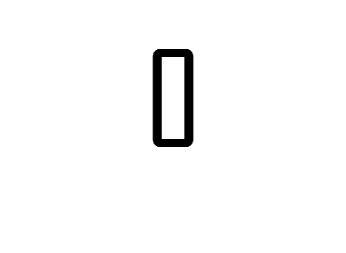

% Image loading and dataset split
% img = readimage(imds,1);
% size(img)

numTrainFiles = 762;
numTestFiles = 254;
trainpath = fullfile('./dataset/train');
testpath = fullfile('./dataset/test');
imdsTrain = imageDatastore(trainpath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
imdsTest = imageDatastore(testpath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain, numTrainFiles, 'randomized');

% augmentation function
function img = randomAugmentation(img)
    % Randomly apply negative effect
    if rand > 0.5
        img = 255 - img;
    end

    % Randomly apply salt & pepper noise
    if rand > 0.5
        img = imnoise(img, 'salt & pepper', 0.02);
    end
end

% imdsTrain.ReadFcn = @(loc)randomAugmentation(imresize(imread(loc), [128, 128]));

taskpath = fullfile('./dataset/task');
imdsTask = imageDatastore(taskpath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

trainSetDetail = countEachLabel(imdsTrain);
testSetDetail = countEachLabel(imdsTest);

img = readimage(imdsTrain,1);
figure;
imshow(img);

size(img)

ans =    128   128


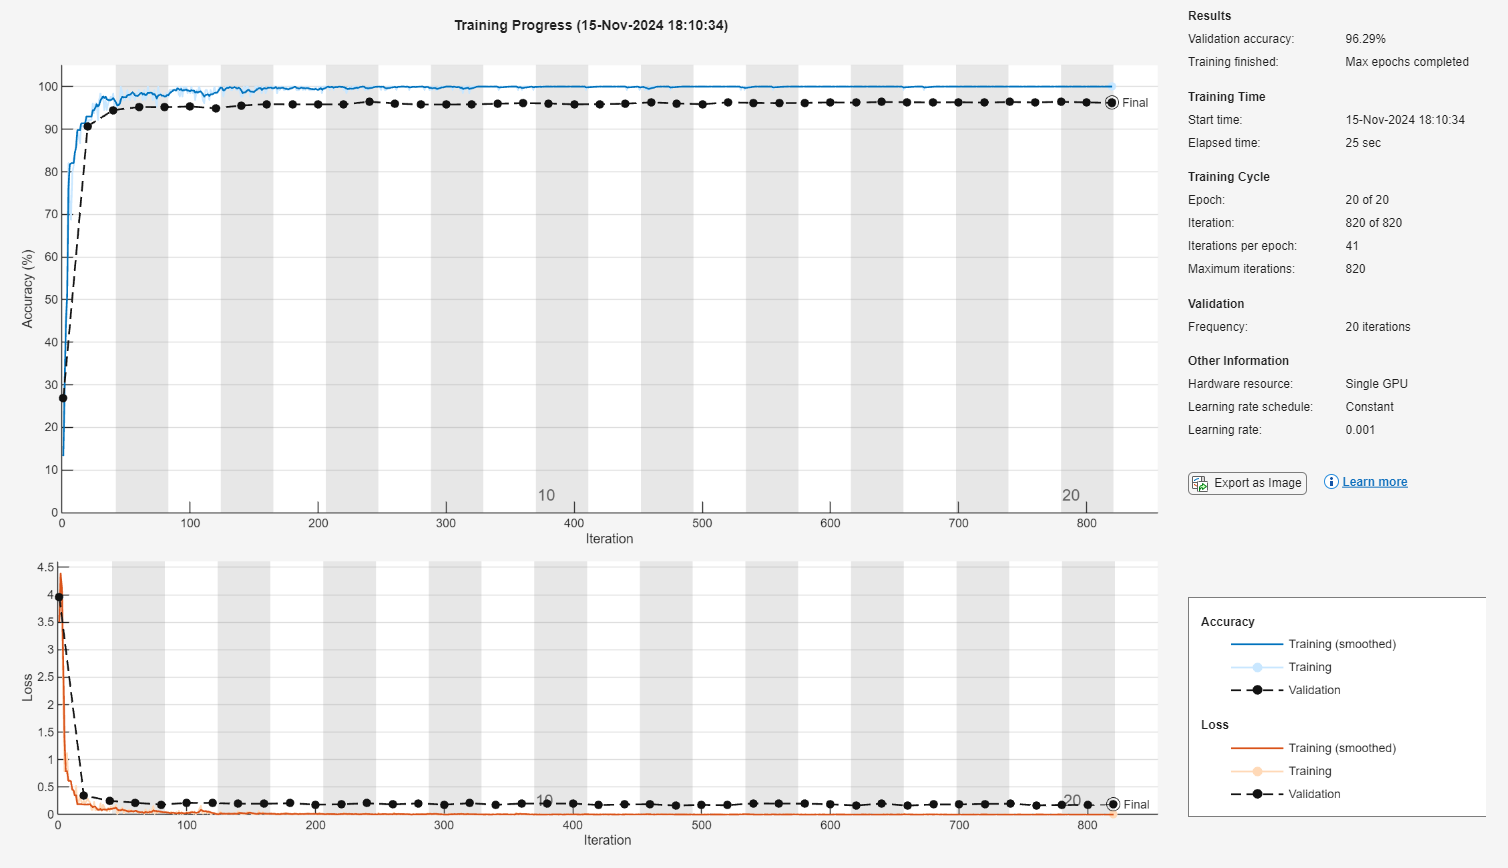


% CNN Architecture
layers = [
    imageInputLayer([128 128 1])
    
    convolution2dLayer(3,8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3,16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3,32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3,64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3,256, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    dropoutLayer
    
    fullyConnectedLayer(7)
    softmaxLayer
    classificationLayer
];
% analyzeNetwork(layers);
% Training Options
options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-3, ...
    'MaxEpochs', 20, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', imdsTest, ...
    'ValidationFrequency', 20, ...
    'MiniBatchSize', 128, ...
    'Verbose', false, ...
    'ExecutionEnvironment', 'auto', ...
    'Plots', 'training-progress');

% Training the Network
net = trainNetwork(imdsTrain, layers, options);

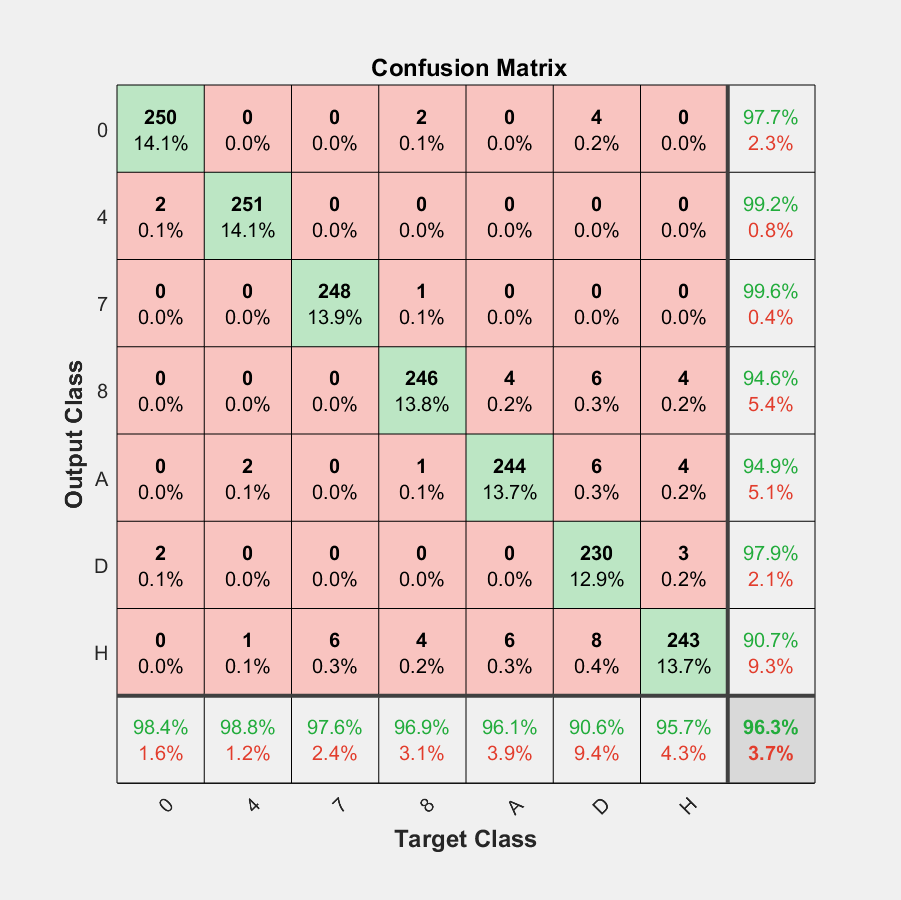

YPred = classify(net, imdsTest);
YTest = imdsTest.Labels;

% Accuracy Calculation
accuracy = sum(YPred == YTest) / numel(YTest);

% Confusion Matrix Display
confMat = confusionmat(YTest, YPred);
% MhelperDisplayConfusionMatrix(confMat)
plotconfusion(YTest, YPred);

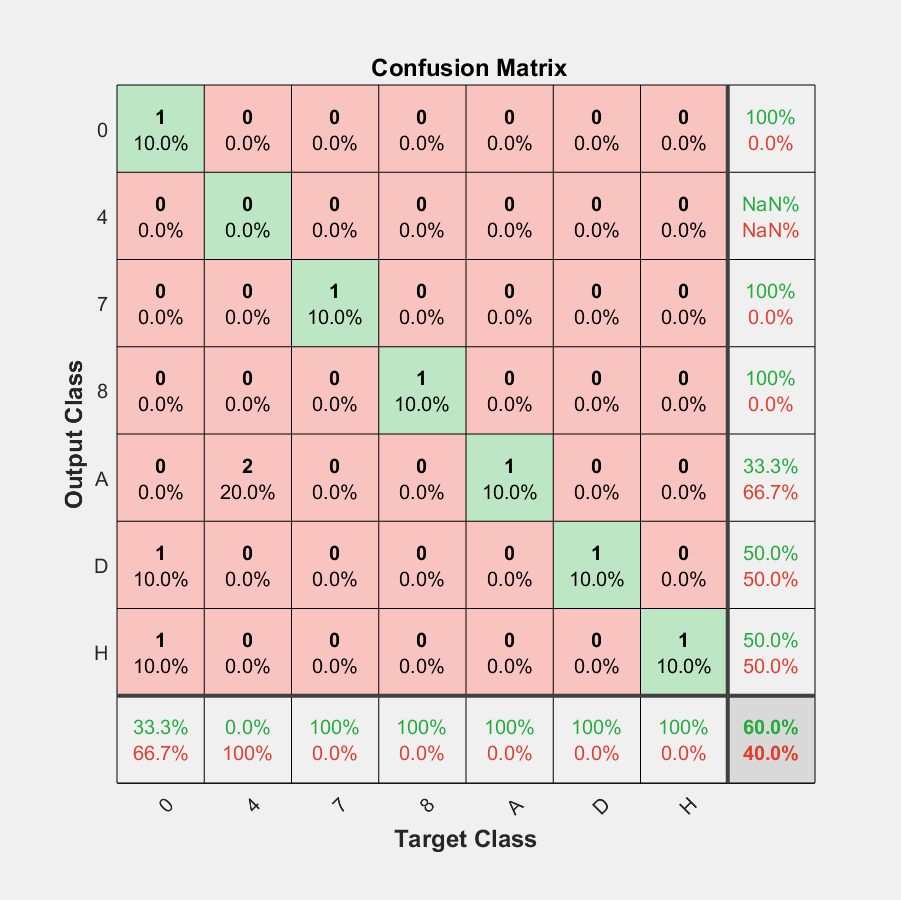


% Task Prediction
imdsTask.ReadFcn = @(loc)im2gray(imresize(imread(loc), [128, 128]));
YTaskpredict = classify(net, imdsTask);
YTrue = imdsTask.Labels;
accuracy = sum(YTaskpredict == YTrue) / numel(YTrue); 
% figure;
confMatTask = confusionmat(YTrue, YTaskpredict);
% MhelperDisplayConfusionMatrix(confMatTask);
plotconfusion(YTrue, YTaskpredict);